# Examining Frequency Over Time

The task of this exercise is to examine an audio signal that changes over time and extract the frequency information. A spectrogram is a 3D visualization that plots frequency on one axis, time on another and uses the color to represent the amplitude (or more frequently power) of the FFT.

The code in this live script will load the data and perform the analysis for you. Your task is to use the control to plot the Fourier Transform for specific times and return the frequency.

## Load the data

[YY,Fs] = audioread("1803_musicdata_voice_2pitches.wav");
% The signal has two channels, let's just take the first channel for
% convenience
y = YY(:,1);

## Create a spectrogram

You don't need to understand all the details of the spectrogram function for this class, but if you are interested in learning more, check out the supplementary live script that walks through the different inputs and their effect on the results.

The code below chunks the data into pieces of 1024 points which represents 21.3 ms of the signal. ($1/F_s * 1024 = 21.3ms$). The chunks have 512 points of overlap (input 3) and we zero-pad the FFT to 2048 points (input 4).

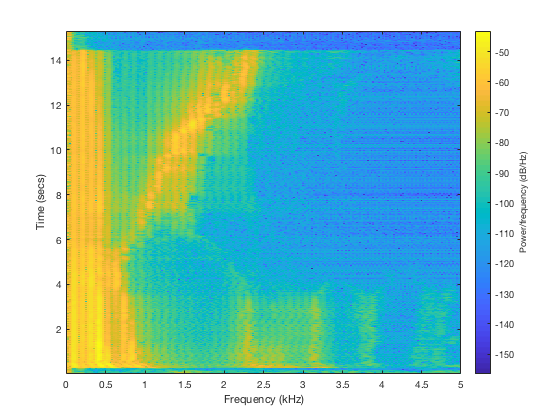

spectrogram(y, 1024, 512, 2048, Fs);
xlim([0 5]) % Set the x axis to 0 to 5 kHz since that is where ost of the frequency information 

The spectrogram function can also return outputs (when requesting output, no visualization is created. So we'll call the spectrogram function again, this time with three outputs

-  The resulting fft for each time point. That is, each rows is a value in frequency axis, and the columns are the time points. We'll use this to create new visualizations below.

- The 2nd output is a vector representing the frequency values

- The 3rd output is a vector representing the time points

[s, f, t] = spectrogram(y, 1024, 512, 2048, Fs);
s = abs(s);  % Take the magnitude of the FFTs

## Examine the FFT at different times

Now we'll look at the resulting FFT at different time points to find the peaks of the frequency. Use the slider to move through the signal in time. The plot will update to show the FFT at the new time and the title will tell you the time in the signal where that FFT occurred. Compare the FFT you see here to the spectrogram above to see if it makes sense. Use the peaks you find to answer the questions in edX.

**Note - If you change the 2nd or 3 inputs to spectrogram above, you may need to double click the control to andjust the values**.

The interactive control should have min = 1, step = 1, and max = length(t).

timePnt = 1071

timePnt = 1071

plot(f, s(:, timePnt))
xlim([0 5000])
xlabel('Frequency (Hz)')
title("FFT at " + num2str(t(timePnt)) + " s")

Now we'll use the `findpeaks` function to get the largest peaks and add them to the plot.

[pks, freq] = findpeaks(s(:, timePnt), f, 'MinPeakProminence',0.02, 'MinPeakDistance', 100);
% Find the indices of the 5 largest peaks (if it finds 3 separate peaks)
[maxPks, pkInd] = maxk(pks, 5);
% Find the frequencies and view them
maxFrequencies = freq(pkInd)

maxFrequencies = 	1.0e+03 *

    1.7109
    0.2109
    1.5938
    0.3281
    0.0938


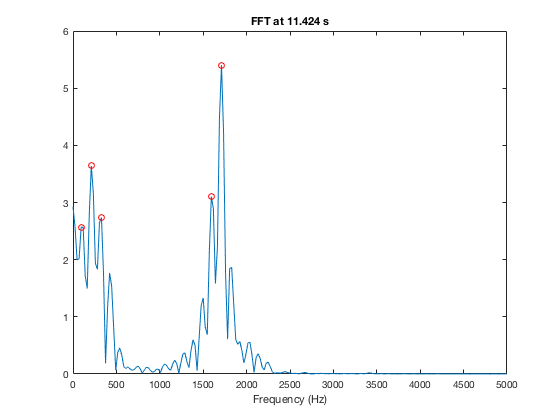

% add them to the plot
hold on
plot(maxFrequencies, maxPks, 'ro')
hold off